# 1、船只信息（不带重物和桅杆）

boat.L = 0.32 %长，单位m

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HL = boat.L/2;

boat.W = 0.16 %宽，单位m

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HW = boat.W/2;

boat.D = 0.12 %高，单位m

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HD = boat.D/2;

boat.mass = 0.1847; %考虑船只所切割木板利用率仅为70%，而且船只为均质的

boat.theta = 135; %倾斜角度
A=boat.D/boat.HW^4;
B=boat.D/boat.HL^2;
% z=1000*x^4+2.5*y^2

# 2、桅杆信息

weigan.mass = 0.107; %单位kg 

weigan.r = 0.005; %单位m

weigan.L = 0.5;

# 3、重物信息

zhongwu.mass = 1.000 ; %单位kg

zhongwu.com = 0.04;

zhongwu.L = 0.10; %单位m
zhongwu.HL = zhongwu.L/2;

zhongwu.r = 0.02;

dx = 0.001;
dy = 0.001;
dz = 0.001;

# 船的微元及体积、质量微元表示

mesh.x = -boat.HW:dx:boat.HW;
mesh.y = -boat.HL:dy:boat.HL;
mesh.z = 0:dz:boat.D;
[mesh.xgrid,mesh.ygrid,mesh.zgrid] = meshgrid(mesh.x,mesh.y,mesh.z)

mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1600 -0.1590 -0.1580 -0.1570 -0.1560 -0.1550 -0.1540 -0.1530 -0.1520 -0.1510 -0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [321×161×121 double]
    ygrid: [321×161×121 double]
    zgrid: [321×161×121 double]
       dv: 1.0000e-09


mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1600 -0.1590 -0.1580 -0.1570 -0.1560 -0.1550 -0.1540 -0.1530 -0.1520 -0.1510 -0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [321×161×121 double]
    ygrid: [321×161×121 double]
    zgrid: [321×161×121 double]
       dv: 1.0000e-09


mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1600 -0.1590 -0.1580 -0.1570 -0.1560 -0.1550 -0.1540 -0.1530 -0.1520 -0.1510 -0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [321×161×121 double]
    ygrid: [321×161×121 double]
    zgrid: [321×161×121 double]
       dv: 1.0000e-09



boat.include = includeBoat(mesh,boat)

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


mesh.dv = dx * dy * dz

mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1600 -0.1590 -0.1580 -0.1570 -0.1560 -0.1550 -0.1540 -0.1530 -0.1520 -0.1510 -0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [321×161×121 double]
    ygrid: [321×161×121 double]
    zgrid: [321×161×121 double]
       dv: 1.0000e-09


total_cube = sum(sum(sum(boat.include)))

total_cube = 3090938

boat.v = total_cube * mesh.dv

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.rho = boat.mass / boat.v

boat = 包含以下字段的 struct :
          L: 0.3200
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


mass_per_cube = mesh.dv * boat.rho  %每个黎曼和立方体质量

mass_per_cube = 5.9755e-08

boat_M_3 = boat.include * mass_per_cube  %整个船的质量三维数组

boat_M_3 = boat_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   

boat_M = sum(boat_M_3(:))

boat_M = 0.1847

boat_M

boat_M = 0.1847

# 重物的微元及体积、质量微元表示

meshzhongwu.x = -zhongwu.r:dx:zhongwu.r;
meshzhongwu.y = -zhongwu.HL:dy:zhongwu.HL;
meshzhongwu.z = 0.00:dz:0.04;

[meshz.xgrid,meshz.ygrid,meshz.zgrid] = meshgrid(meshzhongwu.x,meshzhongwu.y,meshzhongwu.z)

meshz = 包含以下字段的 struct :
    xgrid: [101×41×41 double]
    ygrid: [101×41×41 double]
    zgrid: [101×41×41 double]
       dv: 1.0000e-09


meshz = 包含以下字段的 struct :
    xgrid: [101×41×41 double]
    ygrid: [101×41×41 double]
    zgrid: [101×41×41 double]
       dv: 1.0000e-09


meshz = 包含以下字段的 struct :
    xgrid: [101×41×41 double]
    ygrid: [101×41×41 double]
    zgrid: [101×41×41 double]
       dv: 1.0000e-09



zhongwu.include = includezhongwu(meshz)

zhongwu = 包含以下字段的 struct :
       mass: 1
        com: 0.0400
          L: 0.1000
         HL: 0.0500
          r: 0.0200
    include: [101×41×41 logical]
          v: 1.0353e-04
        rho: 8.6936e+03


meshz.dv = dx * dy * dz

meshz = 包含以下字段的 struct :
    xgrid: [101×41×41 double]
    ygrid: [101×41×41 double]
    zgrid: [101×41×41 double]
       dv: 1.0000e-09


total_zhongwu_cube = sum(sum(sum(zhongwu.include)))

total_zhongwu_cube = 103525

zhongwu.v = total_zhongwu_cube * meshz.dv

zhongwu = 包含以下字段的 struct :
       mass: 1
        com: 0.0400
          L: 0.1000
         HL: 0.0500
          r: 0.0200
    include: [101×41×41 logical]
          v: 1.0353e-04
        rho: 8.6936e+03


zhongwu.rho = zhongwu.mass / zhongwu.v

zhongwu = 包含以下字段的 struct :
       mass: 1
        com: 0.0400
          L: 0.1000
         HL: 0.0500
          r: 0.0200
    include: [101×41×41 logical]
          v: 1.0353e-04
        rho: 9.6595e+03


zhongwumass_per_cube = meshz.dv * zhongwu.rho  %每个黎曼和立方体质量

zhongwumass_per_cube = 9.6595e-06

zhongwu_M_3 = zhongwu.include * zhongwumass_per_cube  %质量三维数组

zhongwu_M_3 = zhongwu_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

zhongwu_M = sum(zhongwu_M_3(:))

zhongwu_M = 1.0000

# 桅杆的微元及体积、质量微元表示

meshweigan.x = -weigan.r:dx:weigan.r;
meshweigan.y = -weigan.r:dy:weigan.r;
meshweigan.z = 0.05:dz:0.55;

[meshw.xgrid,meshw.ygrid,meshw.zgrid] = meshgrid(meshweigan.x,meshweigan.y,meshweigan.z)

meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09



weigan.include = includeweigan(meshw,weigan)

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


meshw.dv = dx * dy * dz

meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


total_weigan_cube = sum(sum(sum(weigan.include)))

total_weigan_cube = 38577

weigan.v = total_weigan_cube * meshw.dv

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


weigan.rho = weigan.mass / weigan.v

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


weiganmass_per_cube = meshw.dv * weigan.rho  %每个黎曼和立方体质量

weiganmass_per_cube = 2.7737e-06

weigan_M_3 = weigan.include * weiganmass_per_cube  %质量三维数组

weigan_M_3 = weigan_M_3(:,:,1) =

   1.0e-05 *

         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    

weigan_M = sum(weigan_M_3(:))   

weigan_M = 0.1070

# 总质量

total_masses = boat_M + zhongwu_M + weigan_M %带重物和桅杆的总质量

total_masses = 1.2917

chishui_v = total_masses / 1000 %吃水体积理论值

chishui_v = 0.0013

# 吃水线（为计算C，计算COM、COB时可以将它注释掉）

% %{
for C=0.06:0.01:0.107 %精度可调
    hullwater = includeWater(C,130,mesh); %倾斜角度可调，以确定C的值
    hull = boat.include & hullwater;
    dv = dx * dy * dz;
    hullcube = sum(sum(sum(hull)));
    v = hullcube * dv;
    fprintf('C = %f, v=%f\n ,zhongwu.mass = %f\n',C,v);
end

C = 0.060000, v=0.001819
 ,zhongwu.mass = C = 0.070000, v=0.001616
 ,zhongwu.mass = C = 0.080000, v=0.001417
 ,zhongwu.mass = C = 0.090000, v=0.001226
 ,zhongwu.mass = C = 0.100000, v=0.001044
 ,zhongwu.mass = 

% }
% 
% fun = @(d) (findMassDiff(d,boat,mesh,zhongwu,weigan));
% depth = fzero(fun,0.0011515)
% 

# COM(加权平均)

COMboat = COM_boat(boat_M_3,mesh)

COMboat =     0.0000   -0.0000    0.0767


COMzhongwu = COM_zhongwu(zhongwu_M_3,meshz)

COMzhongwu =     0.0000    0.0000    0.0268


COMweigan = COM_weigan(weigan_M_3,meshw)

COMweigan =     0.0000   -0.0000    0.3000


COM = (boat_M * COMboat + zhongwu_M * COMzhongwu + weigan_M * COMweigan) / total_masses %总质心

COM =     0.0000    0.0000    0.0565


# COB

吃水部分表示

hullwater = includeWater(0.094,boat.theta,mesh); %吃水线区域07
hullwaterz = includeWaterz(0.094,boat.theta,meshz); 
hullwaterw = includeWaterw(0.094,boat.theta,meshw); 

船体

hullboatwater = boat.include & hullwater %船体浸在水中的部分 hullboatwater

hullboatwater = 321×161×121 logical 数组
hullboatwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

boatwater_M_3 = hullboatwater * mass_per_cube

boatwater_M_3 = boatwater_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

COB_V.boatB_M = sum(boatwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.0660
    zhongwuB_M: 0
     weiganB_M: 0.0974


重物

hullzhongwuwater = zhongwu.include & hullwaterz %重物浸在水中的部分 hullzhongwuwater

hullzhongwuwater = 101×41×41 logical 数组
hullzhongwuwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

zhongwuwater_M_3 = hullzhongwuwater * zhongwumass_per_cube

zhongwuwater_M_3 = zhongwuwater_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

COB_V.zhongwuB_M = sum(zhongwuwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.0660
    zhongwuB_M: 0
     weiganB_M: 0.0974


桅杆

hullweiganwater = weigan.include & hullwaterw %桅杆浸在水中的部分 hullweiganwater

hullweiganwater = 11×11×501 logical 数组
hullweiganwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0


hullweiganwater(:,:,2) =

   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   

weiganwater_M_3 = hullweiganwater * weiganmass_per_cube

weiganwater_M_3 = weiganwater_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


weiganwater_M_3(:,:,2) =

     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0   

COB_V.weiganB_M = sum(weiganwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.0660
    zhongwuB_M: 0
     weiganB_M: 0.0974


COBboat = COB_boat(boatwater_M_3,mesh)

COBboat =     0.0335   -0.0000    0.0953


COBzhongwu = COB_zhongwu(zhongwuwater_M_3,meshz)

COBzhongwu =    NaN   NaN   NaN


COBweigan = COB_weigan(weiganwater_M_3,meshw)

COBweigan =     0.0000   -0.0000    0.3225


综合（浮心）

if(norm(COBzhongwu)>0 && norm(COBweigan)>0)
    total_underwater_masses = COB_V.boatB_M + COB_V.zhongwuB_M + COB_V.weiganB_M
    COB = (COB_V.boatB_M * COBboat + COB_V.zhongwuB_M * COBzhongwu + COB_V.weiganB_M * COBweigan) / total_underwater_masses
elseif(norm(COBzhongwu)>0)
    total_underwater_masses = COB_V.boatB_M + COB_V.zhongwuB_M
    COB = (COB_V.boatB_M * COBboat + COB_V.zhongwuB_M * COBzhongwu) / total_underwater_masses
elseif(norm(COBweigan)>0)
    total_underwater_masses = COB_V.boatB_M + COB_V.weiganB_M
    COB = (COB_V.boatB_M * COBboat + COB_V.weiganB_M * COBweigan) / total_underwater_masses
else
    total_underwater_masses = COB_V.boatB_M
    COB = (COB_V.boatB_M * COBboat) / total_underwater_masses
end

total_underwater_masses = 0.1634

COB =     0.0135   -0.0000    0.2307


%     total_underwater_masses = COB_V.boatB_M
%     COB = (COB_V.boatB_M * COBboat) / total_underwater_masses

# 复原力矩

COB_plot = COB

COB_plot =     0.0135   -0.0000    0.2307


COM_plot = COM

COM_plot =     0.0000    0.0000    0.0565


R = COB - COM

R =     0.0135   -0.0000    0.1742


R1 = COM - COB;
Fb = (total_masses) * 9.8

Fb = 12.6587

% Fbi = -sind(boat.theta)
% Fbk = cosd(boat.theta)

force =2*[-Fb*sind(boat.theta),0,Fb*cosd(boat.theta)]

force =   -17.9020         0  -17.9020


danwei_force=(1/norm(force))*force;
theta=(acosd(dot(R1,force)/(norm(R1)*norm(force))));
bian=norm(R)*cosd(theta);
bianxiangliang=bian*danwei_force;
RR=bianxiangliang-R1

RR =    -0.0803   -0.0000    0.0803


moment = cross(RR,force)

moment =     0.0000   -2.8760   -0.0000


torques = [];
torques = [torques,moment(1)]

torques = 1.1869e-17

% a=norm(moment)
% tau = norm(T)
torques(:,1)

ans = 1.1869e-17

# 图像

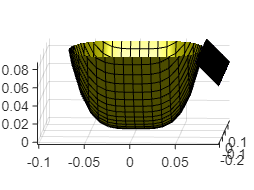

[x,y]=meshgrid(-0.5:0.01:0.5);

z1=(boat.D/boat.HW^4)*x.^4+(boat.D/boat.HL^2)*y.^2;
z2=tand(boat.theta).*x+0.16+y.*0;
surf(x,y,z1,'FaceColor','yellow')
hold on
surf(x,y,z2)
% alpha(.6)
% surf(x,y,z,'FaceColor','red','EdgeColor','none')
camlight left; lighting phong
axis([-0.1 0.1 -0.2 0.2 0 0.09])
daspect([0.1 0.1 0.1])

xlim([-0.102 0.098])
ylim([-0.226 0.174])
zlim([-0.0023 0.0877])

view([1.7523 3.8318])

# 自定义函数：

function hullBoat = includeBoat(mesh,boat) %船体区域
    % 描绘出像乐高积木一样小船的微元，这里的 hullBoat 是三维数组，也是矩阵
    x = mesh.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    y = mesh.ygrid;
    z=(boat.D/boat.HW^4)*x.^4+(boat.D/boat.HL^2)*y.^2;
%     z= -boat.HD*cosd(x*pi/boat.HW)+boat.HD + -boat.HD*cosd(y*pi/boat.HL)+boat.HD;
    %z= ((4*boat.D)./(boat.W^2+4*boat.t*boat.W)).*x.^2+((8*boat.t*boat.D)./(boat.W^2+4*boat.t*boat.D)).*abs(x)+((4*boat.D)./(boat.L^2)).*y.^2;   % 曲面方程
    hullBoat = mesh.zgrid > z;
end

function hullzhongwu = includezhongwu(meshz) %重物区域
    x = meshz.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    z = meshz.zgrid;
    t = x.^2+(z-0.03).^2;   % 曲面方程
    hullzhongwu = t < 0.0004;
end

function hullweigan = includeweigan(meshw,weigan) %桅杆区域
    x = meshw.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    y = meshw.ygrid;
    t = x.^2+y.^2;   % 曲面方程
    hullweigan = t < weigan.r^2;
end

function hullWater = includeWater(B,theta,mesh) %吃水区域
x = mesh.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = mesh.zgrid < z;
    else
            hullWater = mesh.zgrid > z;
    end
end

function hullWater = includeWaterz(B,theta,meshz) %吃水区域
x = meshz.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = meshz.zgrid < z;
    else
            hullWater = meshz.zgrid > z;
    end
end

function hullWater = includeWaterw(B,theta,meshw) %吃水区域
x = meshw.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = meshw.zgrid < z;
    else
            hullWater = meshw.zgrid > z;
    end
end

function COM = COM_boat(boat_M_3,mesh) %船体COM
    M = sum(boat_M_3(:));
    
    xcom = sum((sum(sum(boat_M_3 .* mesh.xgrid)))) / M;
    ycom = sum((sum(sum(boat_M_3 .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(boat_M_3 .* mesh.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COM = COM_zhongwu(zhongwu_M_3,meshz) %重物COM
    M = sum(zhongwu_M_3(:));
    
    xcom = sum((sum(sum(zhongwu_M_3 .* meshz.xgrid)))) / M;
    ycom = sum((sum(sum(zhongwu_M_3 .* meshz.ygrid)))) / M;
    zcom = sum((sum(sum(zhongwu_M_3 .* meshz.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COM = COM_weigan(weigan_M_3,meshw) %桅杆COM
    M = sum(weigan_M_3(:));
    
    xcom = sum((sum(sum(weigan_M_3 .* meshw.xgrid)))) / M;
    ycom = sum((sum(sum(weigan_M_3 .* meshw.ygrid)))) / M;
    zcom = sum((sum(sum(weigan_M_3 .* meshw.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COB = COB_boat(boatwater_M_3,mesh) %船体COB
    M = sum(boatwater_M_3(:));
    
    xcom = sum((sum(sum(boatwater_M_3 .* mesh.xgrid)))) / M;
    ycom = sum((sum(sum(boatwater_M_3 .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(boatwater_M_3 .* mesh.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];
end

function COB = COB_zhongwu(zhongwuwater_M_3,meshz) %重物COB
    M = sum(zhongwuwater_M_3(:));
    
    xcom = sum((sum(sum(zhongwuwater_M_3 .* meshz.xgrid)))) / M;
    ycom = sum((sum(sum(zhongwuwater_M_3 .* meshz.ygrid)))) / M;
    zcom = sum((sum(sum(zhongwuwater_M_3 .* meshz.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];
end

function COB = COB_weigan(weiganwater_M_3,meshw) %桅杆COB
    M = sum(weiganwater_M_3(:));
    
    xcom = sum((sum(sum(weiganwater_M_3 .* meshw.xgrid)))) / M;
    ycom = sum((sum(sum(weiganwater_M_3 .* meshw.ygrid)))) / M;
    zcom = sum((sum(sum(weiganwater_M_3 .* meshw.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];
end